# HOMEWORK 3

## cleanup

clear
clc
close all

## 1.a

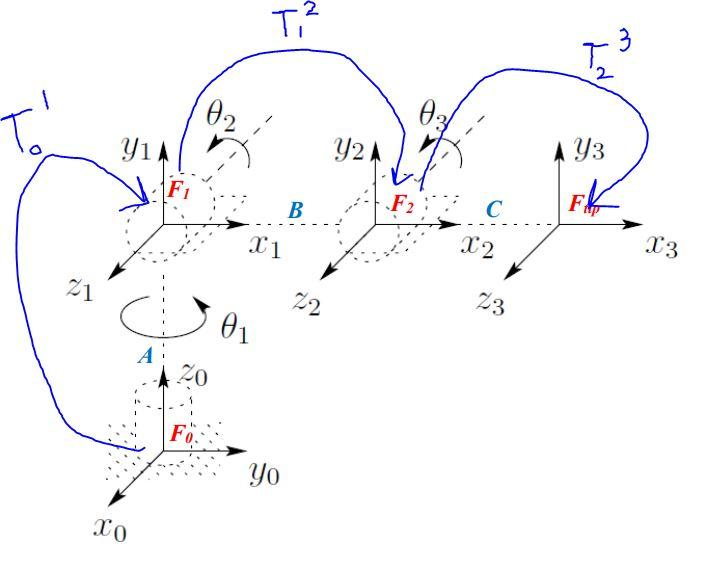

## 1.b

%define our symbolic DH params
syms A B C q1 q2 q3

%put them in a matrix to be retrieved and modified easily
DHsym = [A q1 + pi/2 0 pi/2;...
       0 q2 B 0;...
       0 q3 C 0]

$$DHsym = \left(\begin{array}{cccc} A & q_{1}+\frac{\pi }{2} & 0 & \frac{\pi }{2}\\ 0 & q_{2} & B & 0\\ 0 & q_{3} & C & 0 \end{array}\right)$$

## 1.c

see end of file to see the function definition (matlab needs function definitions at the end of a file)

## 1.d

define each of the transformation matrices 

T01sym = makeDHtrans(DHsym(1,1), DHsym(1,2), DHsym(1,3), DHsym(1,4))

$$T01sym = \left(\begin{array}{cccc} \cos\left(q_{1}+\frac{\pi }{2}\right) & 0 & \sin\left(q_{1}+\frac{\pi }{2}\right) & 0\\ \sin\left(q_{1}+\frac{\pi }{2}\right) & 0 & -\cos\left(q_{1}+\frac{\pi }{2}\right) & 0\\ 0 & 1 & 0 & A\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12sym = makeDHtrans(DHsym(2,1), DHsym(2,2), DHsym(2,3), DHsym(2,4))

$$T12sym = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & B\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & B\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23sym = makeDHtrans(DHsym(3,1), DHsym(3,2), DHsym(3,3), DHsym(3,4))

$$T23sym = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & C\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & C\,\sin\left(q_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## 1.e

calculate the forward transformation from base to tip

T03sym = T01sym * T12sym * T23sym

$$T03sym = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sigma_{2}-\sigma_{2}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & -\cos\left(q_{2}\right)\,\sigma_{2}\,\sin\left(q_{3}\right)-\cos\left(q_{3}\right)\,\sigma_{2}\,\sin\left(q_{2}\right) & \sigma_{1} & B\,\cos\left(q_{2}\right)\,\sigma_{2}+C\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sigma_{2}-C\,\sigma_{2}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sigma_{1}-\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\,\sigma_{1} & -\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\,\sigma_{1}-\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\,\sigma_{1} & -\sigma_{2} & B\,\cos\left(q_{2}\right)\,\sigma_{1}+C\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sigma_{1}-C\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\,\sigma_{1}\\ \cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & 0 & A+B\,\sin\left(q_{2}\right)+C\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+C\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+\frac{\pi }{2}\right)\\ \sigma_{2}=\cos\left(q_{1}+\frac{\pi }{2}\right) \end{array}$$

## 1.f

solve numerically for each of the new matrices substituting theta1 = 15deg, theta2 = 30deg, theta3 = -15deg, A=60, B=40, C = 20 

15deg = pi/12 rad, 30deg = pi/6 rad

DHval = subs(DHsym, [q1, q2, q3, A, B, C], [pi/12, pi/6, -pi/12, 30, 20, 20]);
T01val = makeDHtrans(DHval(1,1), DHval(1,2), DHval(1,3), DHval(1,4))

$$T01val = \left(\begin{array}{cccc} \frac{\sqrt{2}}{4}-\frac{\sqrt{6}}{4} & 0 & \frac{\sqrt{2}}{4}+\frac{\sqrt{6}}{4} & 0\\ \frac{\sqrt{2}}{4}+\frac{\sqrt{6}}{4} & 0 & \frac{\sqrt{6}}{4}-\frac{\sqrt{2}}{4} & 0\\ 0 & 1 & 0 & 30\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12val = makeDHtrans(DHval(2,1), DHval(2,2), DHval(2,3), DHval(2,4))

$$T12val = \left(\begin{array}{cccc} \frac{\sqrt{3}}{2} & -\frac{1}{2} & 0 & 10\,\sqrt{3}\\ \frac{1}{2} & \frac{\sqrt{3}}{2} & 0 & 10\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23val = makeDHtrans(DHval(3,1), DHval(3,2), DHval(3,3), DHval(3,4))

$$T23val = \left(\begin{array}{cccc} \frac{\sqrt{2}}{4}+\frac{\sqrt{6}}{4} & \frac{\sqrt{6}}{4}-\frac{\sqrt{2}}{4} & 0 & 5\,\sqrt{2}+5\,\sqrt{6}\\ \frac{\sqrt{2}}{4}-\frac{\sqrt{6}}{4} & \frac{\sqrt{2}}{4}+\frac{\sqrt{6}}{4} & 0 & 5\,\sqrt{2}-5\,\sqrt{6}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## 1.g

determine the approach vector along the x axis relative to frame 3 re-define T03 with the newly substituted values

T03val = T01val * T12val * T23val;
% extract the x-dir vector (which is the approach vector)
approachX = T03val(1:3,1)

$$approachX = \begin{array}{l} \left(\begin{array}{c} \frac{\sqrt{3}\,\sigma_{1}\,\left(\frac{\sqrt{2}}{4}+\frac{\sqrt{6}}{4}\right)}{2}-\sigma_{1}\,\left(\frac{\sqrt{2}}{8}-\frac{\sqrt{6}}{8}\right)\\ \frac{\sqrt{3}\,{\left(\frac{\sqrt{2}}{4}+\frac{\sqrt{6}}{4}\right)}^{2}}{2}-\sigma_{1}\,\left(\frac{\sqrt{2}}{8}+\frac{\sqrt{6}}{8}\right)\\ \frac{\sqrt{2}}{8}+\frac{\sqrt{6}}{8}+\frac{\sqrt{3}\,\sigma_{1}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}}{4}-\frac{\sqrt{6}}{4} \end{array}$$

## 1.h

take the time derivative of the 3x1 posn vector from 1.e to determine fwd velocity kinematics

xt = T03sym(1:3, 4) % rows 1-3 of column 4

$$xt = \begin{array}{l} \left(\begin{array}{c} B\,\cos\left(q_{2}\right)\,\sigma_{2}+C\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sigma_{2}-C\,\sigma_{2}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ B\,\cos\left(q_{2}\right)\,\sigma_{1}+C\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sigma_{1}-C\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\,\sigma_{1}\\ A+B\,\sin\left(q_{2}\right)+C\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+C\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+\frac{\pi }{2}\right)\\ \sigma_{2}=\cos\left(q_{1}+\frac{\pi }{2}\right) \end{array}$$

diffP03 = diff(xt, q1)

$$diffP03 = \begin{array}{l} \left(\begin{array}{c} C\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\,\sigma_{1}-C\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sigma_{1}-B\,\cos\left(q_{2}\right)\,\sigma_{1}\\ B\,\cos\left(q_{2}\right)\,\sigma_{2}+C\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sigma_{2}-C\,\sigma_{2}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+\frac{\pi }{2}\right)\\ \sigma_{2}=\cos\left(q_{1}+\frac{\pi }{2}\right) \end{array}$$

## 1.i

determine the robot's full velocity kinematics aka solve for the 6x3 jacobian

% define the blank 6x3 jacobian
syms J;
% complete the 'top half'
J(1:3, 1) = diff(xt, q1);
J(1:3, 2) = diff(xt, q2);
J(1:3, 3) = diff(xt, q3);
% we know the next part will always be zeros
J(4:6, 1) = [0 0 1];

% this is the part with the switch statement and extracting rotation
% vectors for the axis where rotation happens
% zeta n * z n-1 (q)
J(4:6, 2) = 1 * T01sym(1:3, 3);

T02sym = T01sym * T12sym;

J(4:6, 3) = 1 * T02sym(1:3, 3);

disp('Jacobian = ');

Jacobian = 


disp(J);

$$\begin{array}{l} \left(\begin{array}{ccc} C\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\,\sigma_{8}-C\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sigma_{8}-B\,\cos\left(q_{2}\right)\,\sigma_{8} & -B\,\sigma_{7}\,\sin\left(q_{2}\right)-\sigma_{4}-\sigma_{3} & -\sigma_{4}-\sigma_{3}\\ B\,\cos\left(q_{2}\right)\,\sigma_{7}+C\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sigma_{7}-C\,\sigma_{7}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & -B\,\sin\left(q_{2}\right)\,\sigma_{8}-\sigma_{6}-\sigma_{5} & -\sigma_{6}-\sigma_{5}\\ 0 & B\,\cos\left(q_{2}\right)+\sigma_{1}-\sigma_{2} & \sigma_{1}-\sigma_{2}\\ 0 & \sigma_{8} & \sigma_{8}\\ 0 & -\sigma_{7} & -\sigma_{7}\\ 1 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=C\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\\ \sigma_{2}=C\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{3}=C\,\cos\left(q_{3}\right)\,\sigma_{7}\,\sin\left(q_{2}\right)\\ \sigma_{4}=C\,\cos\left(q_{2}\right)\,\sigma_{7}\,\sin\left(q_{3}\right)\\ \sigma_{5}=C\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\,\sigma_{8}\\ \sigma_{6}=C\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\,\sigma_{8}\\ \sigma_{7}=\cos\left(q_{1}+\frac{\pi }{2}\right)\\ \sigma_{8}=\sin\left(q_{1}+\frac{\pi }{2}\right) \end{array}$$

## 1.j

i. numerically solve for the jacobian if it is in 1.f

% ii. what is the instantaneous 6x1 velocity vector if all joints have an
% instantaneous angular velocity of positive 30deg/s?

Jval = subs(J, [q1, q2, q3, A, B, C], [pi/12, pi/6, -pi/12, 30, 20, 20])

$$Jval = \begin{array}{l} \left(\begin{array}{ccc} 10\,\sigma_{7}\,\sigma_{6}-10\,\sqrt{3}\,\sigma_{6}-10\,\sqrt{3}\,{\sigma_{6}}^{2} & \sigma_{1}-\sigma_{2}-10\,\sigma_{7}\,\sigma_{6}-\sigma_{5} & -10\,\sigma_{7}\,\sigma_{6}-\sigma_{5}\\ 10\,\sqrt{3}\,\sigma_{7}-10\,{\sigma_{7}}^{2}+\sigma_{4} & -10\,{\sigma_{6}}^{2}-\sigma_{2}-\sigma_{1}-\sigma_{4} & -10\,{\sigma_{6}}^{2}-\sigma_{4}\\ 0 & 10\,\sqrt{3}-\sigma_{2}+\sigma_{1}+10\,\sqrt{3}\,\sigma_{6} & \sigma_{1}-\sigma_{2}+10\,\sqrt{3}\,\sigma_{6}\\ 0 & \sigma_{6} & \sigma_{6}\\ 0 & \sigma_{3} & \sigma_{3}\\ 1 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{5\,\sqrt{6}}{2}\\ \sigma_{2}=\frac{5\,\sqrt{2}}{2}\\ \sigma_{3}=\frac{\sqrt{6}}{4}-\frac{\sqrt{2}}{4}\\ \sigma_{4}=10\,\sqrt{3}\,\sigma_{7}\,\sigma_{6}\\ \sigma_{5}=10\,\sqrt{3}\,{\sigma_{7}}^{2}\\ \sigma_{6}=\frac{\sqrt{2}}{4}+\frac{\sqrt{6}}{4}\\ \sigma_{7}=\frac{\sqrt{2}}{4}-\frac{\sqrt{6}}{4} \end{array}$$


qdot = [pi/6; pi/6; pi/6];

disp('instVel(1:3) is in cm/s');

instVel(1:3) is in cm/s


disp('intsVel(4:6) in rad/s');

intsVel(4:6) in rad/s



instVel = Jval * qdot 

$$instVel = \begin{array}{l} \left(\begin{array}{c} -\frac{\pi \,\left(10\,\sigma_{6}\,\sigma_{5}+\sigma_{4}\right)}{6}-\frac{\pi \,\left(10\,\sigma_{6}\,\sigma_{5}+\sigma_{2}-\sigma_{1}+\sigma_{4}\right)}{6}-\frac{\pi \,\left(10\,\sqrt{3}\,\sigma_{5}-10\,\sigma_{6}\,\sigma_{5}+10\,\sqrt{3}\,{\sigma_{5}}^{2}\right)}{6}\\ \frac{\pi \,\left(10\,\sqrt{3}\,\sigma_{6}-10\,{\sigma_{6}}^{2}+\sigma_{3}\right)}{6}-\frac{\pi \,\left(10\,{\sigma_{5}}^{2}+\sigma_{2}+\sigma_{1}+\sigma_{3}\right)}{6}-\frac{\pi \,\left(10\,{\sigma_{5}}^{2}+\sigma_{3}\right)}{6}\\ \frac{\pi \,\left(\sigma_{1}-\sigma_{2}+10\,\sqrt{3}\,\sigma_{5}\right)}{6}+\frac{\pi \,\left(10\,\sqrt{3}-\sigma_{2}+\sigma_{1}+10\,\sqrt{3}\,\sigma_{5}\right)}{6}\\ \frac{\pi \,\sigma_{5}}{3}\\ -\frac{\pi \,\sigma_{6}}{3}\\ \frac{\pi }{6} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{5\,\sqrt{6}}{2}\\ \sigma_{2}=\frac{5\,\sqrt{2}}{2}\\ \sigma_{3}=10\,\sqrt{3}\,\sigma_{6}\,\sigma_{5}\\ \sigma_{4}=10\,\sqrt{3}\,{\sigma_{6}}^{2}\\ \sigma_{5}=\frac{\sqrt{2}}{4}+\frac{\sqrt{6}}{4}\\ \sigma_{6}=\frac{\sqrt{2}}{4}-\frac{\sqrt{6}}{4} \end{array}$$

## 1.c

function [transMatrix] = makeDHtrans(d, theta, a, alpha)
%MAKEDHTRANS return symbolic representation of trans matrix
%            given symbolic DH inputs
%   either accepts numeric values or symbolic vars
%   then returns corrosponding numeric or symbolic matrix

d = sym(d);
theta = sym(theta);
a = sym(a);
alpha = sym(alpha);

cosT = cos(theta);
sinT = sin(theta);

cosA = cos(alpha);
sinA = sin(alpha);

transMatrix = ...
    [cosT    -sinT*cosA    sinT*sinA    a*cosT;...
    sinT     cosT*cosA     -cosT*sinA   a*sinT;...
    0        sinA          cosA         d;...
    0        0             0            1];


end